clear

X_train = readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Retake\X_train.csv');
y_train = readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Retake\y_train.csv');
X_test = readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Retake\X_test.csv');
y_test = readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Retake\y_test.csv');

X_train = table2array(X_train);
y_train = table2array(y_train);
X_test = table2array(X_test);
y_test = table2array(y_test);

num_samples_train = 5000; % Number of training samples
num_samples_test = 1000;  % Number of test samples

random_indices_train = randperm(size(X_train, 1), num_samples_train);
X_train_subset = X_train(random_indices_train, :);

y_train_subset = y_train(random_indices_train, :);

random_indices_test = randperm(size(X_test,1), num_samples_test);
X_test_subset = X_test(random_indices_test, :);

y_test_subset = y_test(random_indices_test, :);


SVMModel = fitcecoc(X_train_subset, y_train_subset, 'Learners', 'svm', 'Coding', 'onevsall');

% Predict on the test data
y_pred = predict(SVMModel, X_test_subset);

% Evaluate the model
accuracy = sum(y_pred == y_test_subset) / numel(y_test_subset);

% Display accuracy
disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 84.2%


% Create a confusion matrix
C = confusionmat(y_test_subset, y_pred);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    98     0     1     2     0     4     0     0     2     0
     0   114     0     0     0     0     1     0     6     0
     3     0    80     5     3     0     1     2     2     0
     2     1     5    89     0     5     0     1     5     0
     0     1     0     1    74     1     3     1     1     6
     1     0     0     7     2    57     3     1    11     1
     1     0     0     0     1     2    88     0     2     0
     0     0     1     1     3     1     0    88     1    13
     3     2     5     1     2     5     3     1    76     2
     3     0     1     2     4     1     1     3     2    78



% Calculate the observed agreement
po = sum(diag(C)) / sum(C(:));

% Calculate the chance agreement
pe = sum(sum(C, 1) .* sum(C, 2)) / sum(C(:))^2;

% Calculate Cohen's Kappa
kappa = (po - pe) / (1 - pe);

disp(['Cohen''s Kappa: ' num2str(kappa)]);

Cohen's Kappa: 0.82447


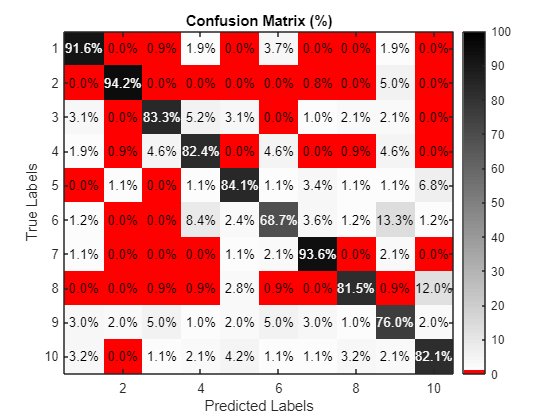

% Create a confusion matrix
C = confusionmat(y_test_subset, y_pred);

% Convert the confusion matrix to a percentage format
C_percent = 100 * C ./ sum(C, 2);

% Define custom colormap with red background and white text
redBackground = [1, 0, 0];
blackText = [0, 0, 0];
whiteText = [1, 1, 1];

% Create a custom colormap with red background and shades of white for text
customColormap = [redBackground; interp1([0, 100], [whiteText; blackText], 1:100)];

% Visualize the confusion matrix as a heatmap using imagesc
figure;
h = imagesc(C_percent);
colorbar;
colormap(customColormap);
clim([0, 100]); % Set the color axis range to match the percentages
title('Confusion Matrix (%)');
xlabel('Predicted Labels');
ylabel('True Labels');

% Display the percentage values on the heatmap in white or black based on intensity
textColors = repmat(C_percent(:) > 50, 1, 3); % Define text colors based on background intensity
textStrings = strtrim(cellstr(num2str(C_percent(:), '%.1f%%'))); % Convert values to string
[x, y] = meshgrid(1:size(C_percent, 2), 1:size(C_percent, 1)); % Create coordinate grid
text(x(:), y(:), textStrings(:), 'HorizontalAlignment', 'center', 'Color', 'k');

% Display the diagonal values in white text on the heatmap
for i = 1:size(C_percent, 1)
    text(i, i, num2str(C_percent(i, i), '%.1f%%'), 'HorizontalAlignment', 'center', 'Color', 'w');
end

% Load the data and preprocess as you did before

% Define the range of hyperparameters to search
boxConstraintValues = [0.01, 0.1, 1, 10]; % Example values for BoxConstraint
kernelFunctions = {'linear', 'polynomial', 'rbf'}; % Example kernel functions

% Initialize variables to store best results
bestAccuracy = 0;
bestBoxConstraint = 0;
bestKernelFunction = '';
bestModel = [];

% Perform Grid Search
for c = boxConstraintValues
    for kernelFunc = kernelFunctions
        % Create SVM template with specific properties
        svmTemplate = templateSVM('KernelFunction', char(kernelFunc), 'BoxConstraint', c);
        
        SVMModel = fitcecoc(X_train_subset, y_train_subset, 'Learners', svmTemplate, 'Coding', 'onevsall');
        
        y_pred_labels = predict(SVMModel, X_test_subset);
        accuracy = sum(y_pred_labels == y_test_subset) / length(y_test_subset);
        
        disp(['BoxConstraint: ' num2str(c) ', KernelFunction: ' char(kernelFunc) ', Accuracy: ' num2str(accuracy)]);
        
        % Update best model if accuracy is better
        if accuracy > bestAccuracy
            bestAccuracy = accuracy;
            bestBoxConstraint = c;
            bestKernelFunction = char(kernelFunc);
            bestModel = SVMModel;
        end
    end
end

BoxConstraint: 0.01, KernelFunction: linear, Accuracy: 0.837
BoxConstraint: 0.01, KernelFunction: polynomial, Accuracy: 0.1
BoxConstraint: 0.01, KernelFunction: rbf, Accuracy: 0.1
BoxConstraint: 0.1, KernelFunction: linear, Accuracy: 0.842
BoxConstraint: 0.1, KernelFunction: polynomial, Accuracy: 0.1
BoxConstraint: 0.1, KernelFunction: rbf, Accuracy: 0.1
BoxConstraint: 1, KernelFunction: linear, Accuracy: 0.842
BoxConstraint: 1, KernelFunction: polynomial, Accuracy: 0.1
BoxConstraint: 1, KernelFunction: rbf, Accuracy: 0.1
BoxConstraint: 10, KernelFunction: linear, Accuracy: 0.842
BoxConstraint: 10, KernelFunction: polynomial, Accuracy: 0.1
BoxConstraint: 10, KernelFunction: rbf, Accuracy: 0.1



disp(['Best BoxConstraint: ' num2str(bestBoxConstraint)]);

Best BoxConstraint: 0.1


disp(['Best KernelFunction: ' bestKernelFunction]);

Best KernelFunction: linear


disp(['Best Accuracy: ' num2str(bestAccuracy)]);

Best Accuracy: 0.842


final_model_svm = fitcecoc(X_train_subset, y_train_subset, 'Learners', templateSVM(...
    'BoxConstraint', 0.1, 'KernelFunction', 'linear'), 'Coding', 'onevsall');